# Sample script of MASKLAYER

 Copyright (c) Shogo MURAMATSU, 2022

 All rights reserved.

type maskLayer

classdef maskLayer < nnet.layer.Layer
    % MASKLAYER
    %
    % Copyright (c) Shogo MURAMATSU, 2022
    % All rights reserved.
    %
    
    properties
        NumberOfChannels
        Mask
    end
        
    methods
        function layer = maskLayer(varargin) 
            p = inputParser;
            addParameter(p,'Name','')
            addParameter(p,'NumberOfChannels',1)
            addParameter(p,'Mask',0)
            parse(p,varargin{:})
            
            % Set layer name.
            layer.Name = p.Results.Name;
            layer.NumberOfChannels = p.Results.NumberOfChannels;
            mask_ = p.Results.Mask;
            layer.Mask = permute(mask_(:).*ones(layer.NumberOfChannels,1),[2 3 1]);

            % Set layer description.
            layer.Description = "MASK for " + layer.NumberOfChannels + " channels";
        end
        
        function Z = predict(layer, X)
            Z = layer.Mask.*X;
        end
    end
end


layer = maskLayer('Name','mask','Mask',0)

layer =   maskLayer のプロパティ:

                Name: 'mask'
    NumberOfChannels: 1
                Mask: 0

   学習可能パラメーター
    プロパティがありません。

   状態パラメーター
    プロパティがありません。

  すべてのプロパティを表示


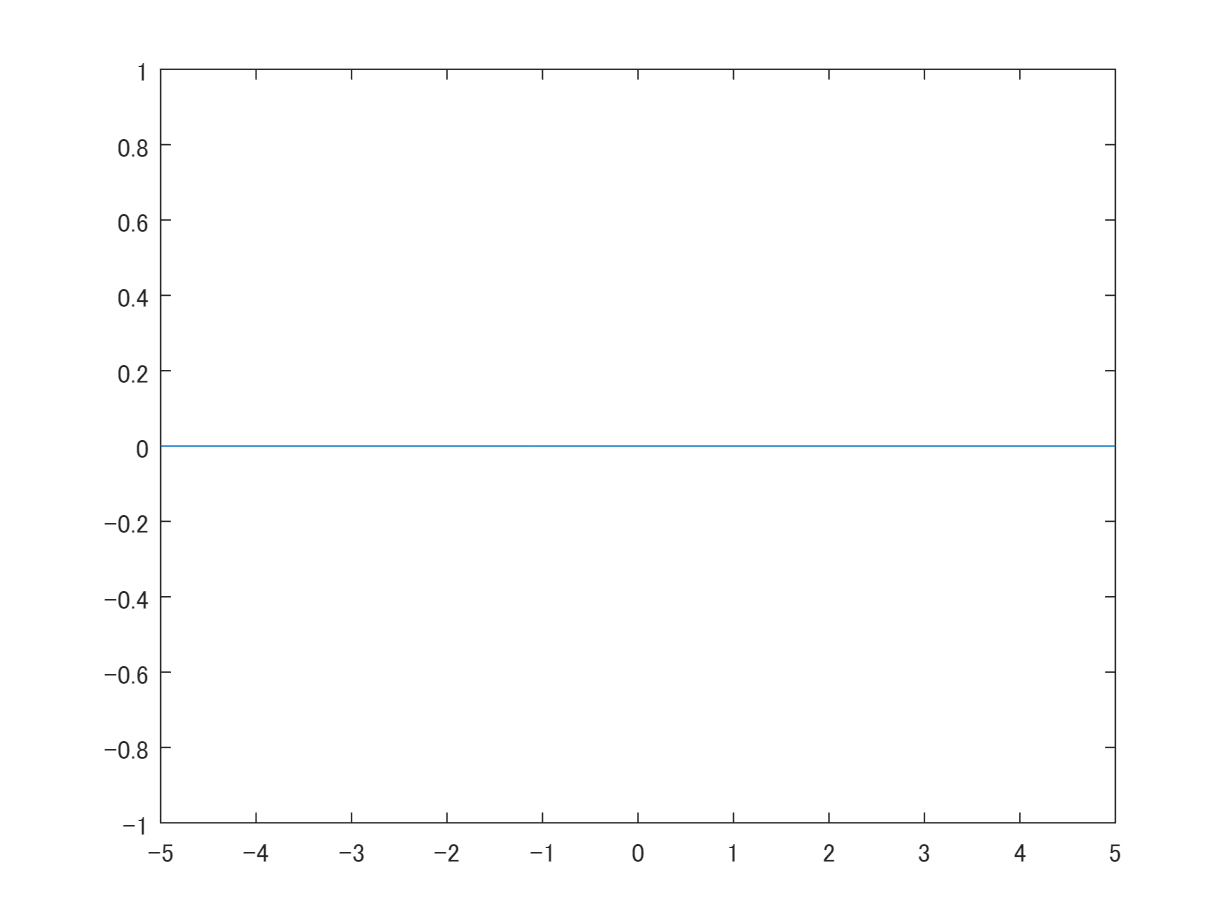

fplot(@(x) extractdata(layer.predict(dlarray(x))))

layer = maskLayer('Name','mask','Mask',1)

layer =   maskLayer のプロパティ:

                Name: 'mask'
    NumberOfChannels: 1
                Mask: 1

   学習可能パラメーター
    プロパティがありません。

   状態パラメーター
    プロパティがありません。

  すべてのプロパティを表示


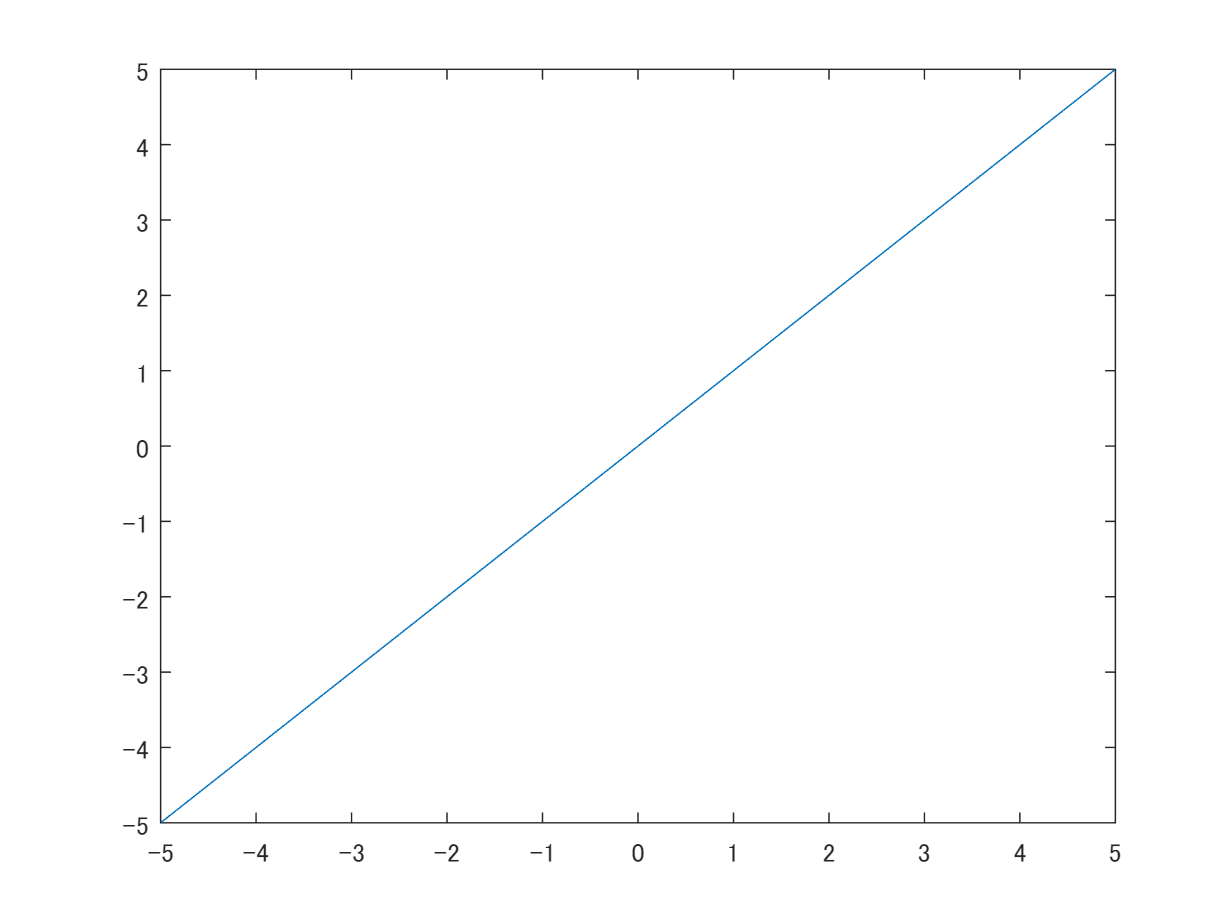

fplot(@(x) extractdata(layer.predict(dlarray(x))))




layer = maskLayer('Name','mask','NumberOfChannels',15,'Mask',[1 0 1 0 1 0 1 0 1 0 1 0 1 0 1])

layer =   maskLayer のプロパティ:

                Name: 'mask'
    NumberOfChannels: 15
                Mask: [1×1×15 double]

   学習可能パラメーター
    プロパティがありません。

   状態パラメーター
    プロパティがありません。

  すべてのプロパティを表示


checkLayer(layer,[24 24 15],'ObservationDimension',4)

コード生成互換性テストをスキップします。コード生成用の層の有効性をチェックするには、'CheckCodegenCompatibility' および 'ObservationDimension' オプションを指定します。
 
nnet.checklayer.TestLayerWithoutBackward を実行しています
.......... .......... ..
nnet.checklayer.TestLayerWithoutBackward が完了しました
__________

テストの概要:
	 22 パス、0 失敗、0 未完了、6 スキップ。
	 経過時間: 0.048943 秒。
